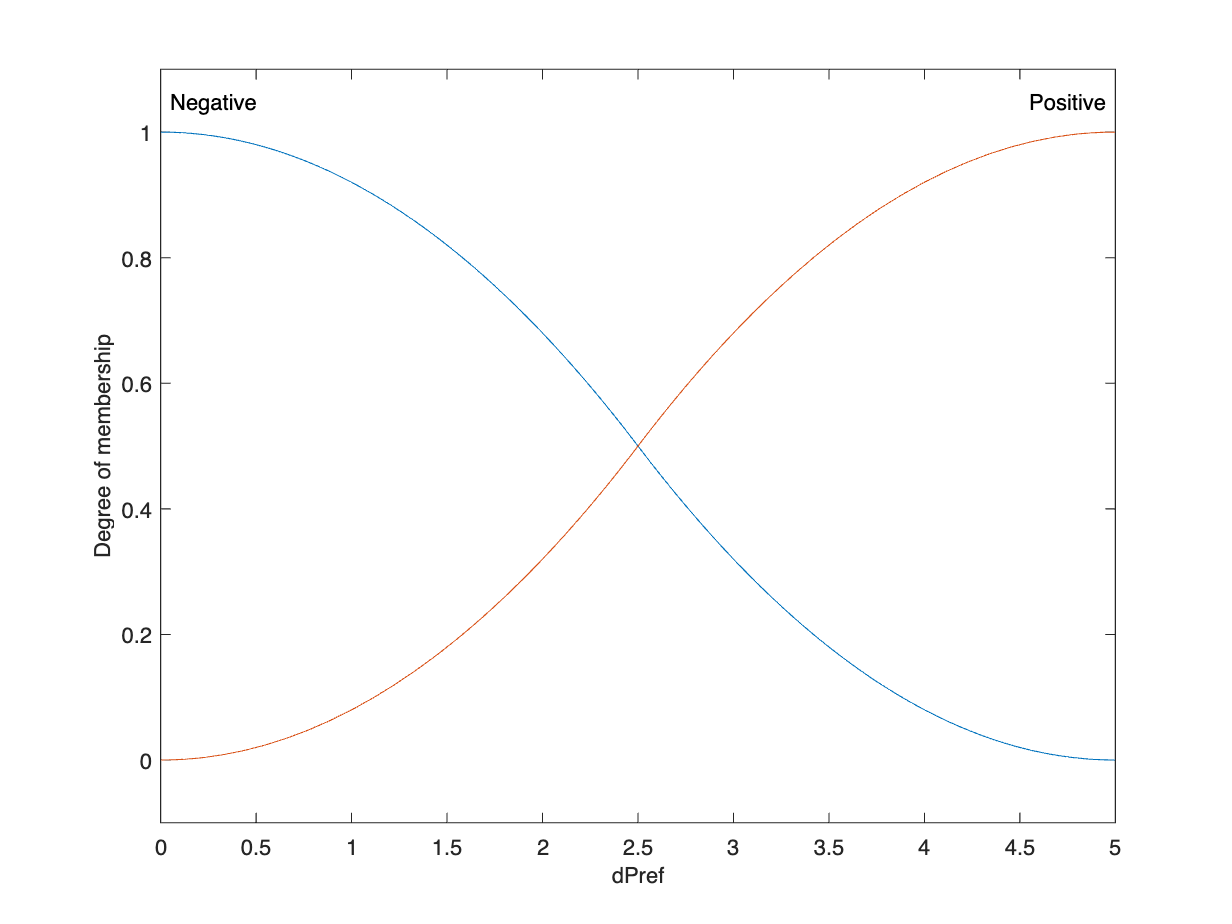

%Neurofeedback Fuzzy inference system
%% Version V3
% Authors - Mario De Los Santos, Felipe Orihuela-Espina, Javier
% Herrara-Vega, Gustavo Rodriguez 
% Date - March 30th, 2022
% Email - madlsh3517@gmail.com


cpWF = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFs', 2, ...
    'AddRule', 'none');

%Inputs

cpWF.Inputs(1).Name = 'dPref';
cpWF.Inputs(1).Range = [0, 5]; 

cpWF.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cpWF.Inputs(1).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
cpWF.Inputs(1).MembershipFunctions(1).Parameters = [0 5];

% cpWF.Inputs(1).MembershipFunctions(2).Name = 'MNegative';
% cpWF.Inputs(1).MembershipFunctions(2).Type ='zmf'; %Z-shaped memebership function
% cpWF.Inputs(1).MembershipFunctions(2).Parameters = [4 5];
% 
% cpWF.Inputs(1).MembershipFunctions(3).Name = 'LPositive';
% cpWF.Inputs(1).MembershipFunctions(3).Type ='smf'; %S-shaped memebersh
% cpWF.Inputs(1).MembershipFunctions(3).Parameters = [5 6];

cpWF.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cpWF.Inputs(1).MembershipFunctions(2).Type ='smf'; %S-shaped memebersh
cpWF.Inputs(1).MembershipFunctions(2).Parameters = [0 5];


plotmf(cpWF, 'input', 1, 1000);

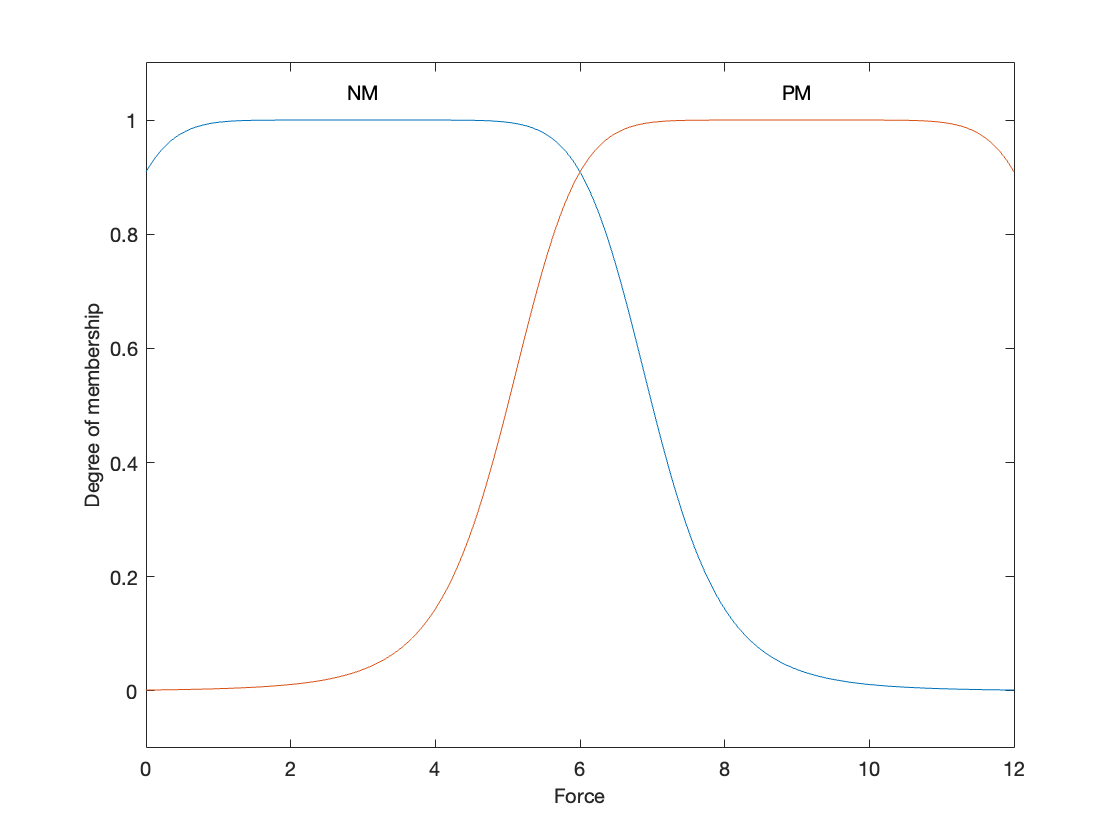

%Outputs

%Basic inference application for control just pressure

cpWF.Outputs(1).Name = 'Force'; %Salida para controlar presion
%cpWF.Outputs(1).Range = [-20,20]; %Rango de la salida del control
cpWF.Outputs(1).Range = [0,12]; %Rango de la salida del control

cpWF.Outputs(1).MembershipFunctions(1).Name = 'NM'; %Negative Low alternative
cpWF.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
cpWF.Outputs(1).MembershipFunctions(1).Parameters = [4,4,3];

% cpWF.Outputs(1).MembershipFunctions(2).Name = 'NM'; %Negative Medium alternative
% cpWF.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; %Generalized bell-shaped membership function
% cpWF.Outputs(1).MembershipFunctions(2).Parameters = [2,2,3];
% 
% cpWF.Outputs(1).MembershipFunctions(3).Name = 'PL'; %Positive Low alternative
% cpWF.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';
% cpWF.Outputs(1).MembershipFunctions(3).Parameters = [2,2,8];

cpWF.Outputs(1).MembershipFunctions(2).Name = 'PM'; %Positive Medium alternative
cpWF.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';
cpWF.Outputs(1).MembershipFunctions(2).Parameters = [4,4,9];



plotmf(cpWF, 'output', 1, 1000);

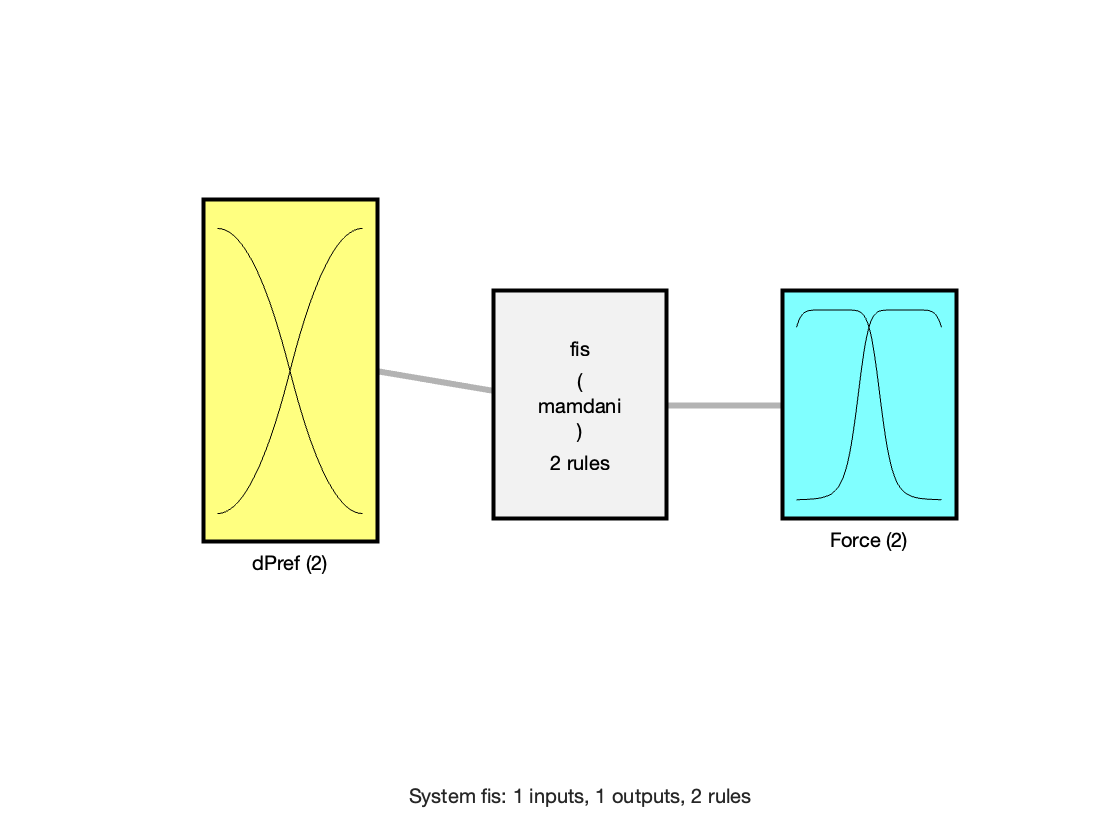

%Inputs:
    % Negative : 
    % MNegative:
    % LPositive:
    % Positive:

% rules = ["If dPref is Negative then Force is NL";...
% %          "If dPref is MNegative then Force is NL";...
% %          "If dPref is LPositive then Force is PM";...
%          "If dPref is Positive then Force is PM"];

rules = ["If dPref is Negative then Force is NM";...
    "If dPref is Positive then Force is PM"];

cpWF = addRule(cpWF, rules); 
figure
plotfis(cpWF)

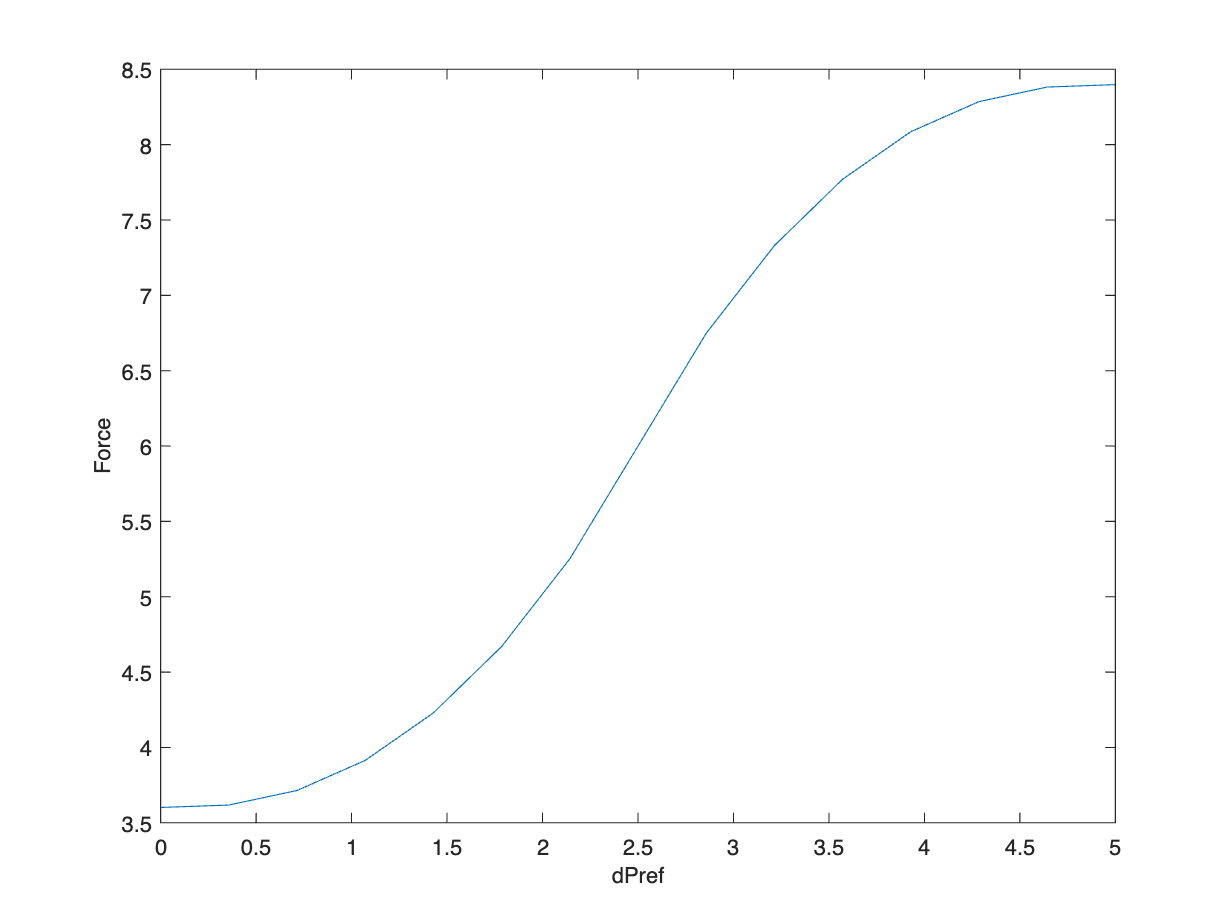

gensurf(cpWF)